clearvars
format shortEng

freq = 50;
T = 1/freq;

percents = [20 40 60 80 100] % corresponding to the measurements

percents =     20.0000e+000    40.0000e+000    60.0000e+000    80.0000e+000   100.0000e+000


% experimental RPM measurement with HTI HT522 Tachometer
rpms = [4600, 7300, 8420, 9220, 10200]

rpms =      4.6000e+003     7.3000e+003     8.4200e+003     9.2200e+003    10.2000e+003


fittedPoly = polyfit(percents, rpms, 3)

fittedPoly =     18.3333e-003    -3.9714e+000   319.2381e+000  -332.0000e+000


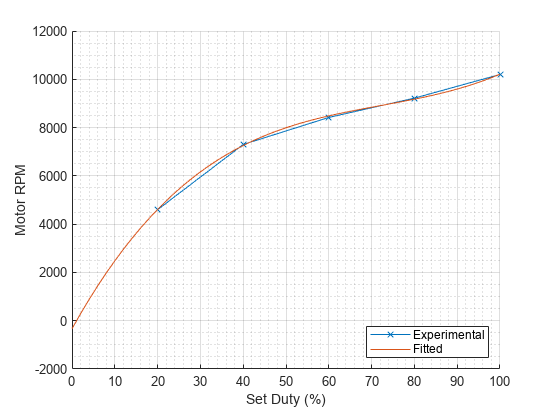


theoPercents = 0:2:100;
theoRpms = polyval(fittedPoly, theoPercents);

figure()
hold on
grid on
grid minor
plot(percents, rpms, "x-")
plot(theoPercents, theoRpms)
xlabel("Set Duty (%)")
ylabel("Motor RPM")
legend("Experimental", "Fitted", Location="southeast")
hold off
saveas(gcf, "graph_duty.png")


%% Expected RPM at maximum using KV
motorKV = 1100;
appliedvoltage = 9;
expectedMaxRPM = motorKV*appliedvoltage

expectedMaxRPM =      9.9000e+003



thousands = percents*10 % corresponding to the measurements

thousands =    200.0000e+000   400.0000e+000   600.0000e+000   800.0000e+000     1.0000e+003


% experimental RPM measurement with HTI HT522 Tachometer
rpms = [4600, 7300, 8420, 9220, 10200]

rpms =      4.6000e+003     7.3000e+003     8.4200e+003     9.2200e+003    10.2000e+003


fittedPoly = polyfit(thousands, rpms, 3)

fittedPoly =     18.3333e-006   -39.7143e-003    31.9238e+000  -332.0000e+000


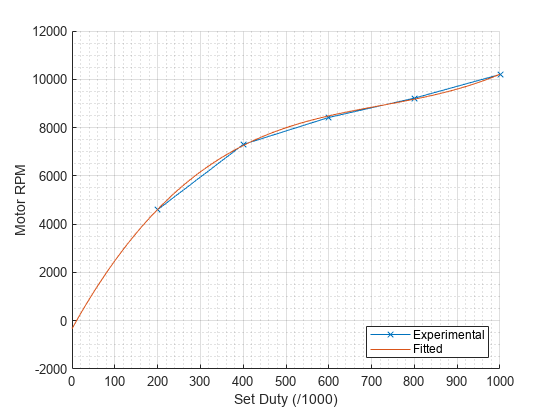


theoThosands = 0:2:1000;
theoRpms = polyval(fittedPoly, theoThosands);

figure()
hold on
grid on
grid minor
plot(thousands, rpms, "x-")
plot(theoThosands, theoRpms)
xlabel("Set Duty (/1000)")
ylabel("Motor RPM")
legend("Experimental", "Fitted", Location="southeast")
hold off
saveas(gcf, "graph_duty_thosand.png")


%% Expected RPM at maximum using KV
motorKV = 1100;
appliedvoltage = 9;
expectedMaxRPM = motorKV*appliedvoltage

expectedMaxRPM =      9.9000e+003


syms x y
y = poly2sym(fittedPoly)

$$y = \frac{5411044928288123\,x^{3}}{295147905179352825856}-\frac{139\,x^{2}}{3500}+\frac{3352\,x}{105}-\frac{1460151441686411}{4398046511104}$$

finv = matlabFunction(finverse(y))

finv = function_handle with value:
    @(x)1.0./(x.*2.727272727272733e+4+sqrt((x.*2.727272727272733e+4-2.431332087713275e+8).^2+2.057590971198525e+14)-2.431332087713275e+8).^(1.0./3.0).*(-5.903637488052969e+4)+(x.*2.727272727272733e+4+sqrt((x.*2.727272727272733e+4-2.431332087713275e+8).^2+2.057590971198525e+14)-2.431332087713275e+8).^(1.0./3.0)+7.220779220779237e+2


finv(9000)

ans =    748.1910e+000


getDuty = finv

getDuty = function_handle with value:
    @(x)1.0./(x.*2.727272727272733e+4+sqrt((x.*2.727272727272733e+4-2.431332087713275e+8).^2+2.057590971198525e+14)-2.431332087713275e+8).^(1.0./3.0).*(-5.903637488052969e+4)+(x.*2.727272727272733e+4+sqrt((x.*2.727272727272733e+4-2.431332087713275e+8).^2+2.057590971198525e+14)-2.431332087713275e+8).^(1.0./3.0)+7.220779220779237e+2


% fittedPolyInverse = polyfit(rpms, thousands, 3)
% theoRpms = 0:50:10e3
% theoThosands = polyval(fittedPolyInverse, theoRpms)
% figure()
% hold on
% grid on
% grid minor
% plot(thousands, rpms, "x-")
% plot(theoThosands, theoRpms)
% xlabel("Set Duty (/1000)")
% ylabel("Motor RPM")
% legend("Experimental", "Fitted", Location="southeast")
% hold off
% saveas(gcf, "graph_duty_thosand_inverse.png")